# ASEN 2003 Lab 3: Crankshaft

clc
clear all

Read in files into discreet tables

% First test, initial theta = 152.5 degrees, subtracting out extra cycles
data5PT = readtable("Test1_5pt5V");
data5PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data5PT.Theta = data5PT.Theta - (floor((data5PT.Theta(1,1)-152.5)/360)*360);
data5PT.totalTurns = (data5PT.Theta - data5PT.Theta(1,1))./360

data5PT = 553×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    342.18    185.24    414.75     -302.55        18               0 
    0.02    350.22    178.88    424.67     -362.82        22        0.022333 
    0.04     359.1    170.73    418.83     -423.99        18           0.047 
    0.06    367.04    162.09    424.83     -451.43        21        0.069056 
    0.08    376.22    152.61    460.83     -494.94        20        0.094556 
     0.1    385.22    142.28    439.67     -540.11        20         0.11956 
    0.12    393.94    131.05    449.67     -575.93        20         0.14378 
    0.14    403.28    119.25    472.7

[time5PT,ind5PT] = min(abs(data5PT.totalTurns-6))

time5PT = 0.0110

ind5PT = 346

data5PT.Time((1:ind5PT),1)

ans =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


data5PT([ind5PT+1:end],:) = []

data5PT = 346×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    342.18    185.24    414.75     -302.55        18               0 
    0.02    350.22    178.88    424.67     -362.82        22        0.022333 
    0.04     359.1    170.73    418.83     -423.99        18           0.047 
    0.06    367.04    162.09    424.83     -451.43        21        0.069056 
    0.08    376.22    152.61    460.83     -494.94        20        0.094556 
     0.1    385.22    142.28    439.67     -540.11        20         0.11956 
    0.12    393.94    131.05    449.67     -575.93        20         0.14378 
    0.14    403.28    119.25    472.7


data6PT = readtable("Test1_6pt5V");
data6PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data6PT.Theta = data6PT.Theta - (floor((data6PT.Theta(1,1)-152.5)/360)*360);
data6PT.totalTurns = (data6PT.Theta - data6PT.Theta(1,1))./360

data6PT = 361×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    323.92    195.82    508.58     -264.62        20               0 
    0.02    334.32    189.51    531.17     -363.14        20        0.028889 
    0.04    345.06    181.37    528.17     -450.22        19        0.058722 
    0.06    355.58    171.59    558.75     -523.73        21        0.087944 
    0.08    367.24    160.52    549.92     -577.02        19         0.12033 
     0.1    377.66    148.39    560.08     -658.08        21         0.14928 
    0.12    389.72    134.25    587.25     -729.61        19         0.18278 
    0.14       401    119.35    576.0


data7PT = readtable("Test1_7pt5V");
data7PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data7PT.Theta = data7PT.Theta - (floor((data7PT.Theta(1,1)-152.5)/360)*360);
data7PT.totalTurns = (data7PT.Theta - data7PT.Theta(1,1))./360

data7PT = 337×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0     404.9     109.4    671.42     -922.31        19               0 
    0.02    418.22    90.286    684.33     -979.25        20           0.037 
    0.04    432.38    70.387     715.5     -1015.3        21        0.076333 
    0.06    446.86     49.98    746.33     -1007.5        20         0.11656 
    0.08     462.3    30.633    791.25      -915.6        20         0.15944 
     0.1    478.46    14.065    826.25     -718.03        20         0.20433 
    0.12    495.28      2.81    855.33      -375.3        20         0.25106 
    0.14     512.4    -0.276    834.5


data8PT = readtable("Test1_8pt5V");
data8PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data8PT.Theta = data8PT.Theta - (floor((data8PT.Theta(1,1)-152.5)/360)*360);
data8PT.totalTurns = (data8PT.Theta - data8PT.Theta(1,1))./360

data8PT = 263×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    492.04     8.138    986.17      -688.6        19               0 
    0.02    511.32     0.015    1011.7     -74.407        20        0.053556 
    0.04    532.32     5.697    1013.3       636.2        20         0.11189 
    0.06    551.26    24.522    904.08      1183.9        21          0.1645 
    0.08    568.38      51.5    789.08      1483.7        20         0.21206 
     0.1    582.82    82.317    663.58      1535.5        19         0.25217 
    0.12    595.42    111.98    634.83      1446.9        21         0.28717 
    0.14    608.32    139.85    611.8


data9PT = readtable("Test1_9pt5V");
data9PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data9PT.Theta = data9PT.Theta - (floor((data9PT.Theta(1,1)-152.5)/360)*360);
data9PT.totalTurns = (data9PT.Theta - data9PT.Theta(1,1))./360

data9PT = 252×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    202.18    45.742    936.83      1718.7        20               0 
    0.02    219.74    82.471    831.08      1840.7        21        0.048778 
    0.04    235.74    117.91    778.08      1753.3        20        0.093222 
    0.06    251.22    151.86    784.08      1590.2        19         0.13622 
    0.08    267.28    180.05    807.25      1184.2        20         0.18083 
     0.1    283.88    197.94    910.25      557.57        21         0.22694 
    0.12    303.28    202.35     926.5     -66.026        19         0.28083 
    0.14    320.76     196.4    908.8


data10PT = readtable("Test1_10pt5V");
data10PT.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
data10PT.Theta = data10PT.Theta - (floor((data10PT.Theta(1,1)-152.5)/360)*360);
data10PT.totalTurns = (data10PT.Theta - data10PT.Theta(1,1))./360

data10PT = 218×7 table
    Time    Theta     yDist     AngVel    SlideSpeed    SampleT    totalTurns
    ____    ______    ______    ______    __________    _______    __________

       0    397.28    125.27    1035.9     -1409.8        19              0  
    0.02    418.52    95.799    1153.7     -1539.1        22          0.059  
    0.04    443.06    64.275    1179.3       -1596        20        0.12717  
    0.06    465.58    33.305    1181.3     -1464.9        20        0.18972  
    0.08    490.72     8.353    1276.6     -899.54        19        0.25956  
     0.1    516.28         0    1306.2      124.57        20        0.33056  
    0.12    542.28    13.727    1217.5      1222.8        20        0.40278  
    0.14    564.58    46.402    1060



% Testing:
beta5PT = betaCalc(0.155,0.075,0.26,data5PT.Theta)

beta5PT =    43.1909
   40.1772
   36.9190
   34.1111
   31.0362
   28.2449
   25.7916
   23.4779
   21.4966
   19.8971


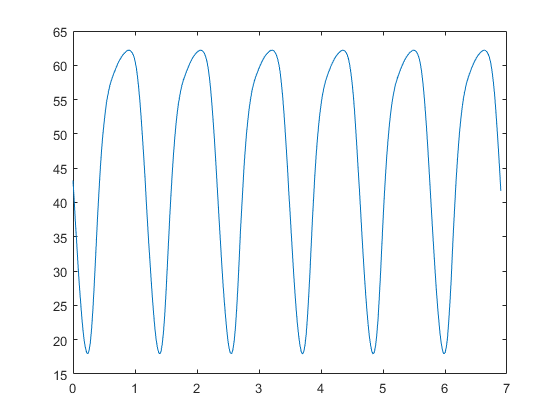

plot(data5PT.Time,beta5PT)


vMod5PT = LCSMODEL(0.075,0.155,0.26,data5PT.Theta,(data5PT.AngVel .* pi)./180)

vMod5PT =     0.8442
    0.7751
    0.6481
    0.5393
    0.4270
    0.2554
    0.1117
   -0.0445
   -0.2022
   -0.3296


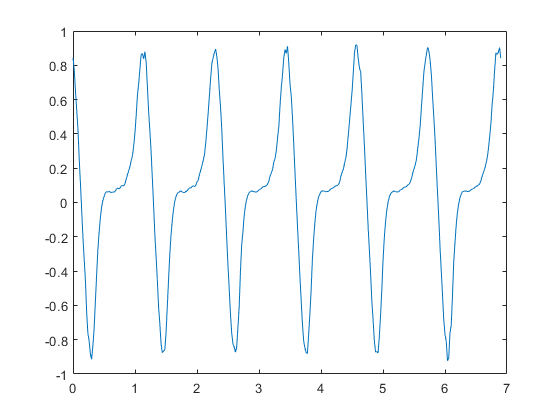

plot(data5PT.Time,vMod5PT)

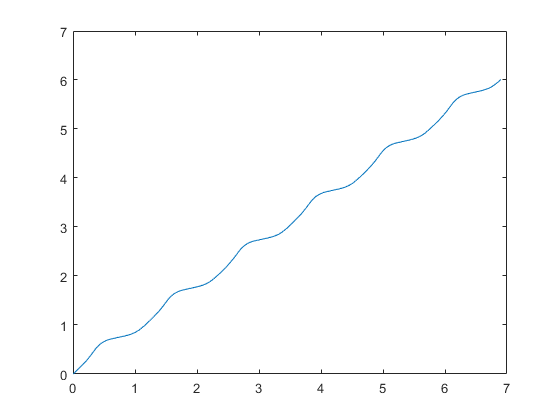


plot(data5PT.Time,data5PT.totalTurns)

function beta = betaCalc(d, r, l, theta)
% Function for calculating angle Beta

beta = asind( (d - r * sind(theta)) / l );

end
function vMod = LCSMODEL(r, d, l, theta, w)
% Function for calculating velocity of collar along y axis

beta = betaCalc(d, r, l, theta);
vMod = -1.*w .* ((r.*cosd(theta) .* (l.*sind(beta) + r.*sind(theta)))./(r.*cosd(theta) - l.*cosd(beta)) + r.*sind(theta));

end